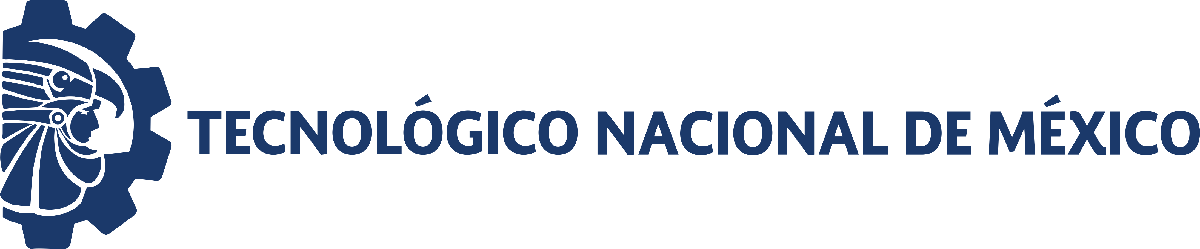                                 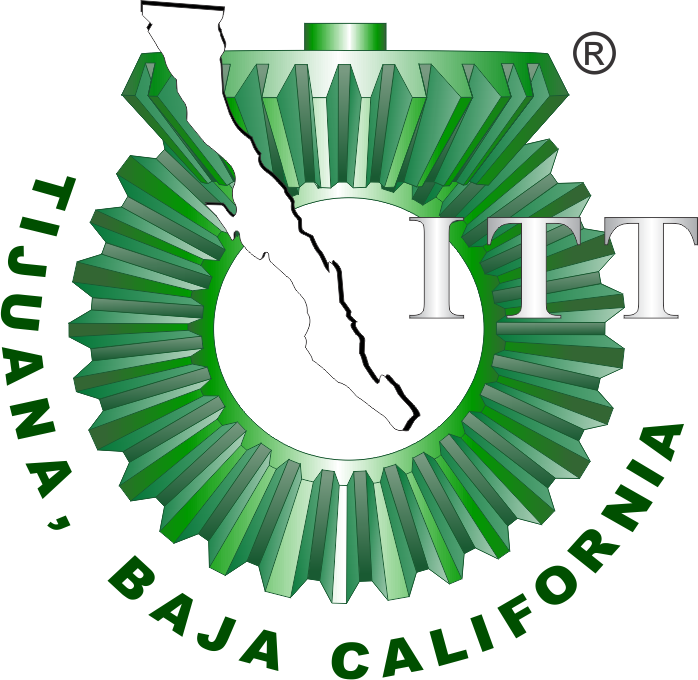

# Práctica tres: Modelado y control del sistema muscoesqueletico 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

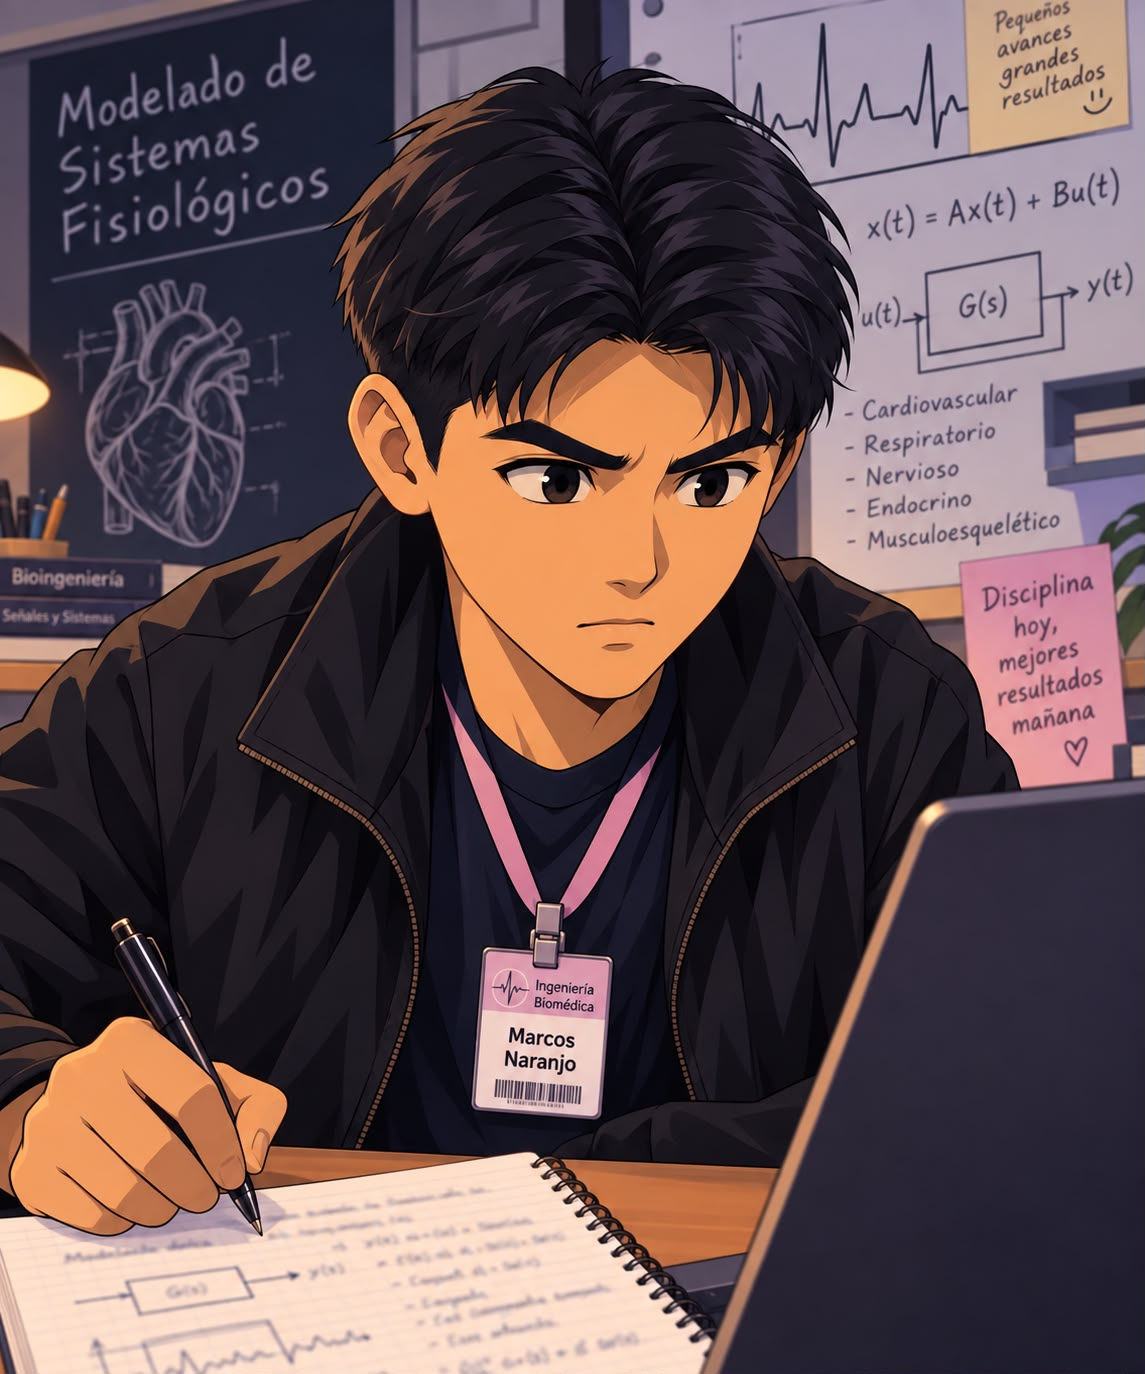

Nombre del alumno: Marcos Ancelmo Naranjo Rivera

Número de control: 23212218

Correo institucional: l23212218**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema3')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistema3',parameters);

## Respuesta al impulso: Control y caso

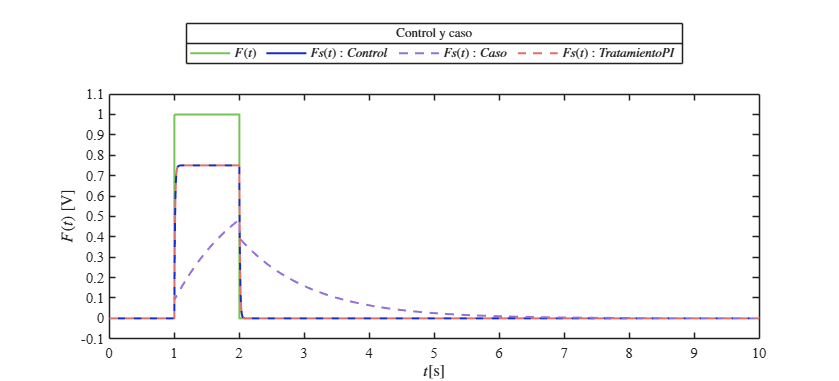

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.FsPI)

## Funcion: Respuestas de la simulacion

function plotsignals (t,c,c1,c2,c3)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,11,5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [118, 196, 87]/255;
    clr2 = [27, 44, 193]/255;
    clr3 = [147, 112, 219]/255;
    clr4 = [221, 113, 113]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    plot(t,c,'-',t,c1,'-',t,c2,'--',t,c3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));

    L = legend('$F(t)$','$Fs(t): Control$','$Fs(t): Caso$', '$Fs(t): Tratamiento PI$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    title(L,'Control y caso')

    xlabel('$t$[s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

exportgraphics(gcf,'Control_caso_matlab3.pdf','contenttype','vector')
end